# **PESTools - Example 021-022 - Processing and Fitting PES spectra**

## Author: PCC

The example shows how to use PESTools to fit the data from an PES experiment using a model that consists of a linear combination of N curves and a global optimisation method to minimise residuals.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

For external data files, all you need to do is define the **x-axis (binding energy)** and **y-axis (intensity) **and all the fitting tools are available to use. This means you can in principle import any type of data you like, even a text file. To be compatible, all you need to do is define a matlab struct(), for example 'xps_dat{1}', with **two** fields:

- Define the **x-axis data** as:    xps_dat{1}**.xdat**

- Deine the **y-axis data **as:     xps_dat{1}**.ydat**

close all; clear all;
pp          = plot_props();
data_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Cronus\PESTools_PCC\Examples\Example_Data\';
save_path   = 'D:\OneDrive\PCC_MS_Project\00_Software_Library\ADRESSTools\ADRESSTools_Cronus\PESTools_PCC\Examples\Example_Data\';

# **(1) XPS Data Processing**

**(A) Loading in the PES data files**

% % Defining many file-names through a keyword
% all_files       = dir(data_path);
% all_files       = {all_files(~[all_files.isdir]).name};
% findx           = find(contains(all_files, "020_XPS_In4d_hv="));
% file_names      = sort(all_files(findx));
% Explicitely defining the file-names
file_names      = {...
    '020_XPS_In4d_hv=550eV.h5',...
    '020_XPS_In4d_hv=750eV.h5',...
    '020_XPS_In4d_hv=950eV.h5',...
    '020_XPS_In4d_hv=1150eV.h5',...
    };
% Load in the data
xps_dat = cell(1,length(file_names));
for i = 1:length(file_names); xps_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...


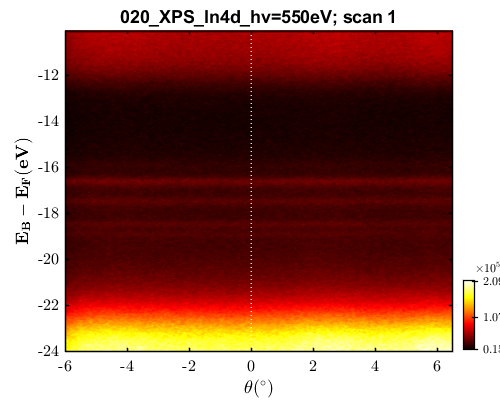

view_arpes_data(xps_dat{1});

**(B) Loading in the Fermi edge reference via gold / copper**

Note, that all PES data should come with a Fermi-edge reference so that the binding energy scale can be properly calibrated.

% % Defining many file-names through a keyword
% all_files       = dir(data_path);
% all_files       = {all_files(~[all_files.isdir]).name};
% findx           = find(contains(all_files, "eV_EF.h5"));
% file_names_ef     = sort(all_files(findx));
% Explicitely defining the file-names
file_names_ef      = {...
    '020_XPS_In4d_hv=550eV_EF.h5',...
    '020_XPS_In4d_hv=750eV_EF.h5',...
    '020_XPS_In4d_hv=950eV_EF.h5',...
    '020_XPS_In4d_hv=1150eV_EF.h5',...
    };
% Load in the data
xps_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); xps_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...
Loading ADRESS data...


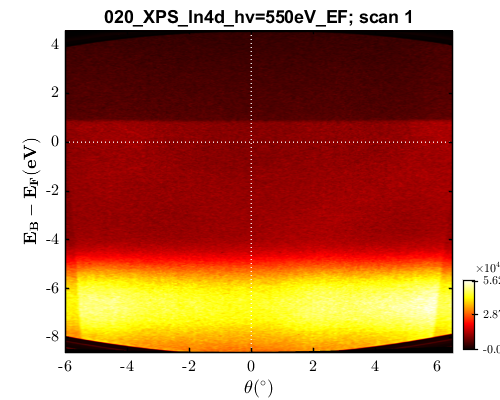

view_arpes_data(xps_ref{1});

**(C) Binding energy alignment to the reference data**

help align_energy;

  dataStr = align_energy(dataStr, align_args, dataStr_ref, plot_result)
    This is a function that will align the 'dataStr' ARPES data-structure 
    to the Fermi-level, VB or CB state. It operates using the
    AlignEF() function conditions, but can also load in a reference data file
    'dataStr_ref' that it will use as the energy reference.
 
    REQ. FUNCTIONS:
    -   [xField, yField, zField, dField] = find_data_fields(dataStr);
    -   [EAlign, EF, Fail] = AlignEF(Data, ECorr [,eWin] [,dEWin] [,dESmooth] [,feat]);
 
    IN:
    -   dataStr:            data structure of the ARPES data.
    -   align_args:         {1×6} cell of {Type,Scans,eWin, dEWin, dESmooth, feat}.
                                Type:       "global"
                                          	"align2ref"
                                        	"align2ref-perchannel"
                                        	"fit2ef" || "fit2ef-95%" (default 95% window size)
                                    

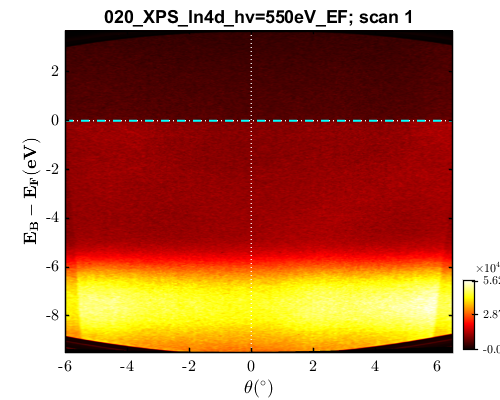

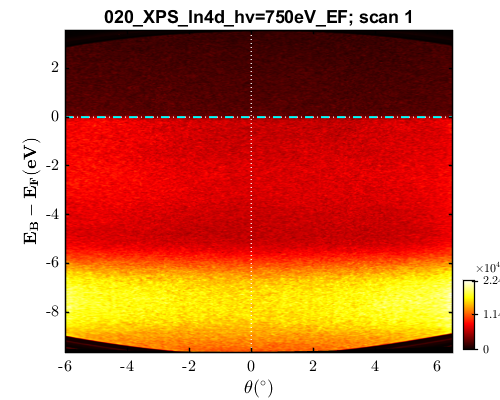

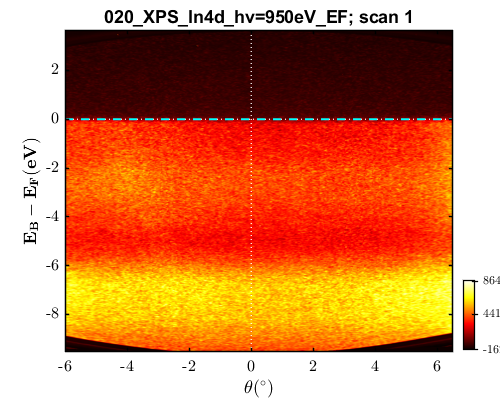

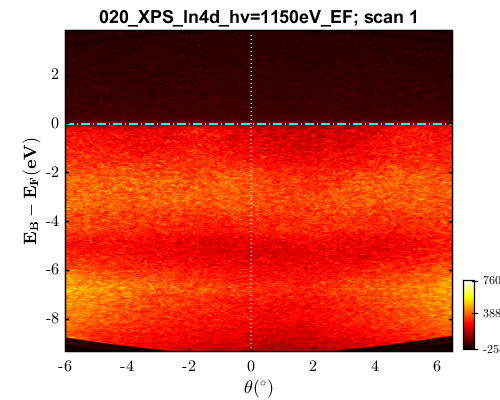

% (1) AUTOMATIC COARSE ALIGNMENT TO THE EDGE OF THE REFERENCE
% -- Coarse alignment of the energy
alignType   = "align2ref";
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 4.00;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(xps_dat)
    xps_dat{i}  = align_energy(xps_dat{i}, align_args, xps_ref{i}); 
    xps_ref{i}.raw_eb = xps_ref{i}.raw_eb - xps_dat{i}.eb_shifts{1};
    view_arpes_data(xps_ref{i}); line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 
end

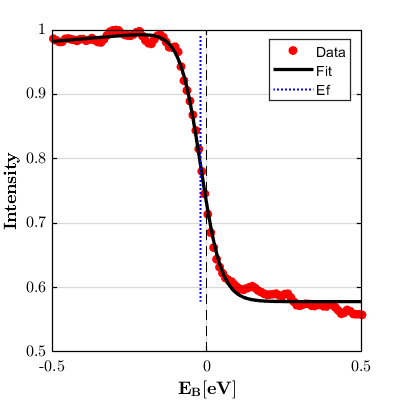

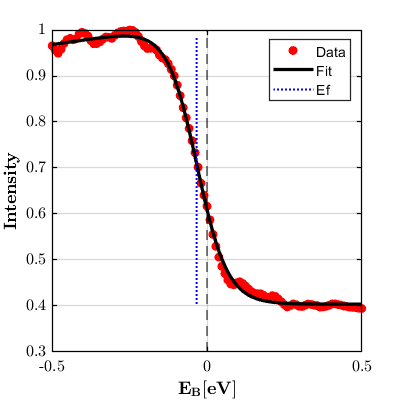

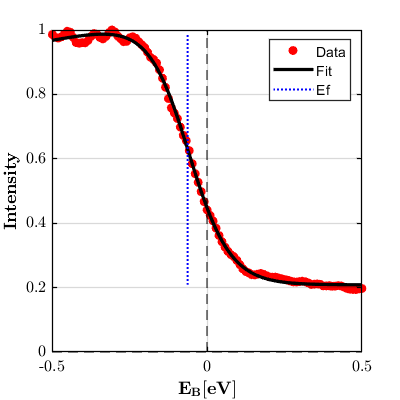

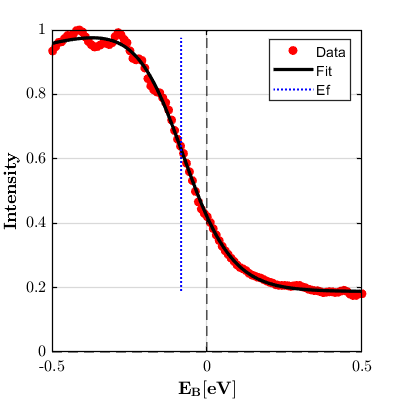

% (2) FITTING TO THE FDD WITH FINE ALIGNMENT
alignType   = "fit2ef-25%"; 
scan_indxs	= [];
eWin        = 0.00;
dEWin       = 0.50;
dESmooth    = [];
feat        = 'edge';
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(xps_dat)
    xps_dat{i}  = align_energy(xps_dat{i}, align_args, xps_ref{i}, 1); 
end

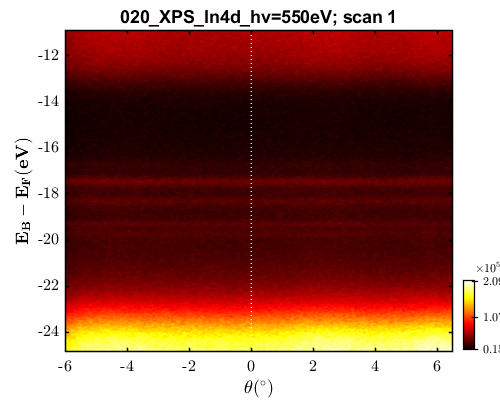

view_arpes_data(xps_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extracting the angle-integrated XPS spectra**

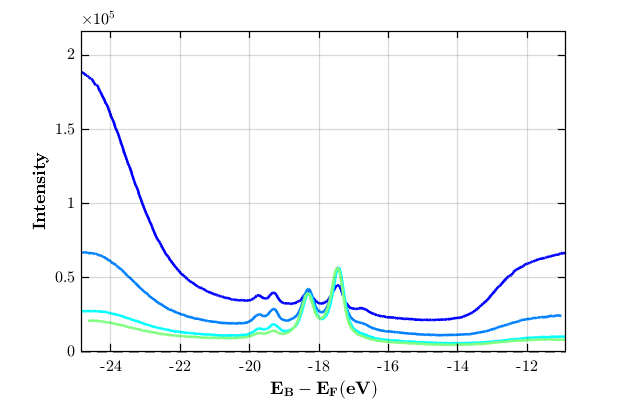

for i = 1:length(xps_dat)
    cutWin      = 0.95*[min(xps_dat{i}.raw_tht(:)), max(xps_dat{i}.raw_tht(:))];      % Integration window of the cut to be made.
    xps_args    = {cutWin};
    [xps_dat{i}, ~] = pes_extract_data(xps_dat{i}, xps_args, 0); 
end
view_pes_data(xps_dat);

**(E) Extracting the principal peak position**

1) x = -17.48 eV, y = 45000.23 


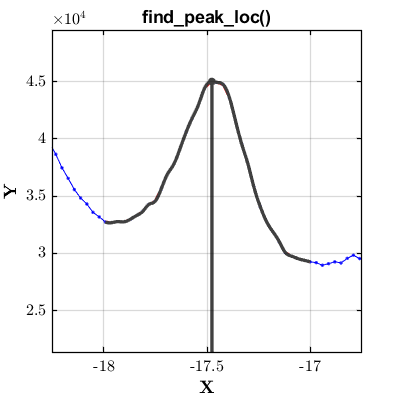

% -- Extracting the energy and intensity of the peak positions
xWin       = -17.5 + 0.5*[-1,1];
for i = 1:length(xps_dat)
    if i == 1;  [xps_dat{i}.peak_loc, xps_dat{i}.peak_int] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 1); 
    else;       [xps_dat{i}.peak_loc, xps_dat{i}.peak_int] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 0); 
    end
end

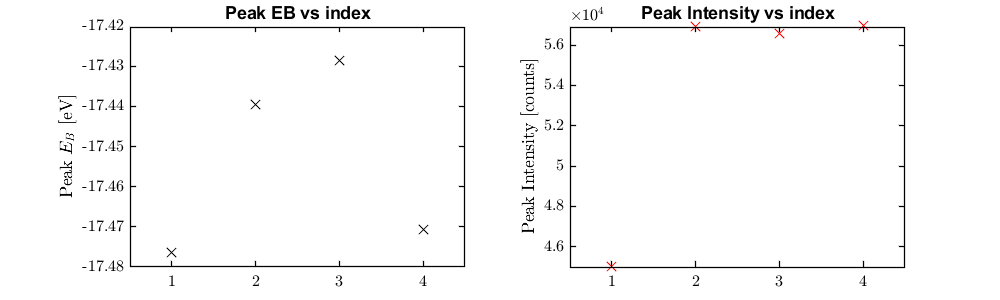

% -- Plotting the comparison
fig1 = figure();
fig1.Position(3) = 2.0*500;
fig1.Position(4) = 1.0*300;
% -- Plotting the Peak Eb position vs Photon Energy
subplot(121); hold on;
for i = 1:length(xps_dat); plot(i, xps_dat{i}.peak_loc, 'kx-', 'markersize', 10); end
gca_props(); xlim([0.5, length(xps_dat)+0.5]);
title('Peak EB vs index');
ylabel('Peak $$E_{B}$$ [eV]', 'interpreter', 'latex');
% -- Plotting the Peak Intensity vs Photon Energy
subplot(122); hold on;
for i = 1:length(xps_dat); plot(i, xps_dat{i}.peak_int, 'rx-', 'markersize', 10); end
gca_props(); xlim([0.5, length(xps_dat)+0.5]);
title('Peak Intensity vs index');
ylabel('Peak Intensity [counts]', 'interpreter', 'latex');

**(F) Normalising the XPS data**

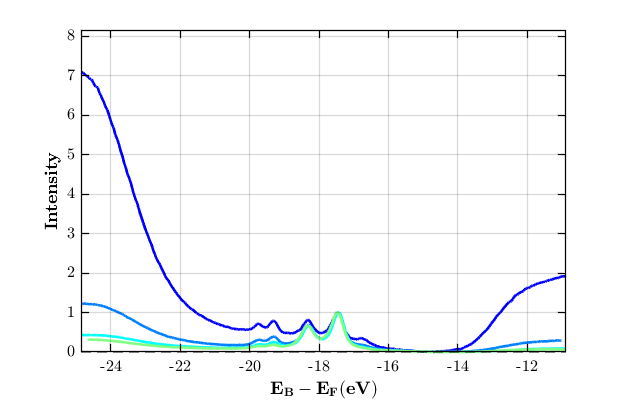

for i = 1:length(xps_dat)
    eWin            = xps_dat{i}.peak_loc;      % approximate Eb position of a peak in the spectrum to normalise to.
    dEWin           = 1.0;                      % can be empty []. Single, constant value that defines the width of the approximate Eb position
    norm_args       = {eWin, dEWin};
    xps_dat{i}.ydat = pes_norm2peak(xps_dat{i}.xdat, xps_dat{i}.ydat, norm_args, 0);
end
view_pes_data(xps_dat);

**(G) Cropping the XPS data**

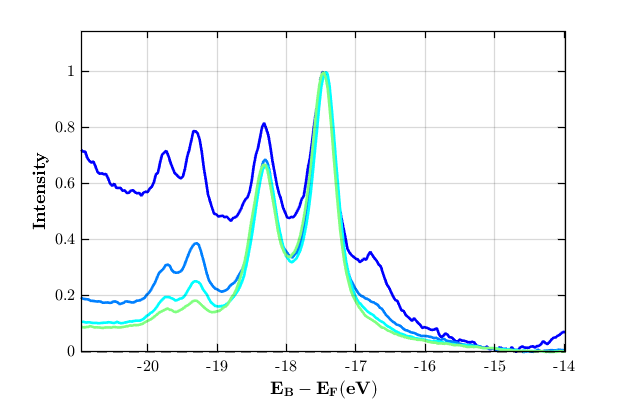

ebLims = xps_dat{1}.peak_loc + [-3.5, 3.5];
for i = 1:length(xps_dat)
    [~, xps_dat{i}.xdat, xps_dat{i}.ydat] = data_crop2D([], xps_dat{i}.xdat, xps_dat{i}.ydat, [], ebLims);
end
view_pes_data(xps_dat);

**(H) View all the XPS data to be fitted**

view_pes_data(xps_dat);

# **(2) FitCL2PEAK: Extracting the Peak Position of the XPS data**

**(A) Initialising the XPS data to be fitted**

xps_fit               = struct();
xps_fit.FileName      = file_names;
xps_fit.repeats       = length(xps_dat);
xps_fit.data          = xps_dat;

**(B) Peak Position Determintion**

1) x = -17.48 eV, y = 1.00 


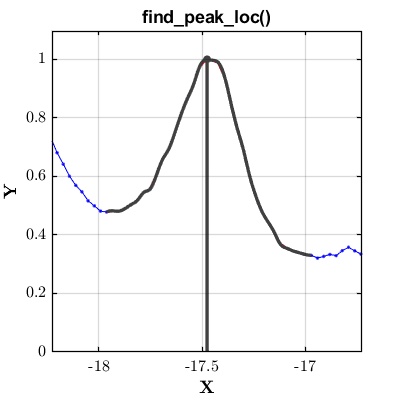

xWin       = xps_fit.data{1}.peak_loc + 0.5*[-1,1];
xps_fit.ECL = []; xps_fit.ECL_int = [];
for i = 1:length(xps_dat)
    if i == 1;  [xps_fit.ECL(i), xps_fit.ECL_int(i)] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 1); 
    else;       [xps_fit.ECL(i), xps_fit.ECL_int(i)] = find_peak_loc(xps_dat{i}.xdat, xps_dat{i}.ydat, xWin, 'spline', 0); 
    end
end

**(C) Finding the best estimate of ECL across the dataset**

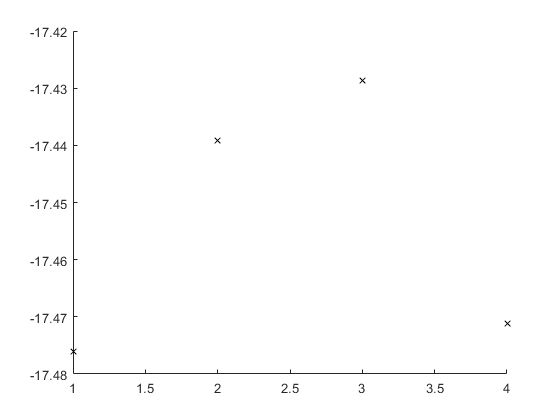

ECL     = zeros(1,length(xps_fit.ECL)); 
for i = 1:length(xps_dat)
    ECL(i)      = xps_fit.ECL(i);
end
% -- Isolating any potential outliers
XX              = 1:length(ECL);
TF              = isoutlier(ECL); % TF(1:end) = 0;
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
ECL_adj{1}      = ECL(~TF);
ECL_adj{2}      = ECL(TF);
% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, ECL_adj{1}, 'kx');

plot(XX_adj{2}, ECL_adj{2}, 'rx');
% -- Redefining ECL
ECL            = ECL(~TF);
% -- Final assignments
ECL_mu         = mean(ECL)

ECL_mu = -17.4537

ECL_3sig       = 3*std(ECL)

ECL_3sig = 0.0703

**(D) -  Saving the SXARPES data & fit results**

% Defining the MATLAB data structure
dataStr_01                         = struct();
% - Best Fit XPS Results
% -- XPS data and corresponding best fits
dataStr_01.repeated_measures       = xps_fit.repeats;
dataStr_01.xps_data                = xps_fit.data;
% -- ECL estimates & measurement uncertainty
dataStr_01.ECL                     = ECL;
dataStr_01.ECL_mu                  = ECL_mu;
dataStr_01.ECL_3sig                = ECL_3sig;
dataStr_01

dataStr_01 = struct with fields:
    repeated_measures: 4
             xps_data: {1×4 cell}
                  ECL: [-17.4760 -17.4391 -17.4286 -17.4712]
               ECL_mu: -17.4537
             ECL_3sig: 0.0703

**(E) -  Saving the corresponding figure & text file with fit results**

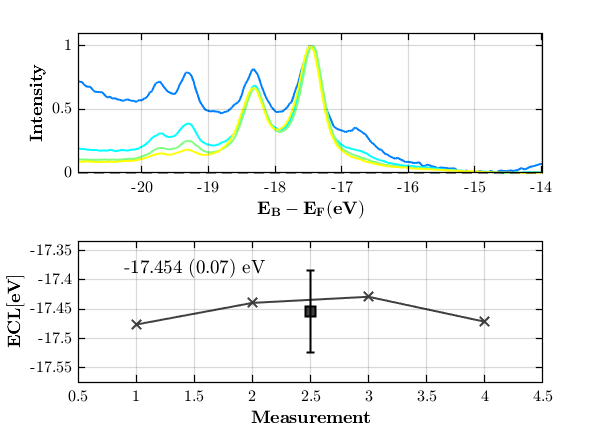

% Initialising the figure
pp  = plot_props();
fig = figure();
fig.Position(3) = 1.50*pp.fig4x4(1);
fig.Position(4) = 1.10*pp.fig4x4(2);

% (1) PLOTTING THE XPS DATA
subplot(2,1,1); hold on;
% -- Plotting all of the curve components
cols = jet(length(xps_fit.data)+1);
for i = 1:length(xps_fit.data)
    plot(dataStr_01.xps_data{i}.xdat, dataStr_01.xps_data{i}.ydat, 'k-', 'color', cols(i,:), 'linewidth', 1.5);
end
% - Formatting the figure
gca_props(); grid on;
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
axis([...
    min(dataStr_01.xps_data{1}.xdat(:)), max(dataStr_01.xps_data{1}.xdat(:)),...
    min(dataStr_01.xps_data{1}.ydat(:)), 1.1*max(dataStr_01.xps_data{1}.ydat(:))]);

% (3) PLOTTING ECL VS MEASUREMENT NUMBER
subplot(2,1,2); hold on;
% Plotting ECL vs measurement number
XX = 1:length(dataStr_01.ECL);
plot(XX, dataStr_01.ECL, 'kx-', 'color', pp.col.fit{1}, 'markerfacecolor', pp.col.fit{1}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), dataStr_01.ECL_mu, dataStr_01.ECL_3sig, dataStr_01.ECL_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{1}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, dataStr_01.ECL_mu-dataStr_01.ECL_3sig-0.05, dataStr_01.ECL_mu+dataStr_01.ECL_3sig+0.05]);
% xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  ECL [eV]  $$', 'Interpreter', 'latex');
ECL_str = string(round(dataStr_01.ECL_mu,3)) + " (" + string(round(dataStr_01.ECL_3sig,3)) + ") eV";
text(0.1,0.8,ECL_str,'Interpreter',"latex",'Units',"normalized",'FontSize',14);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');


% (4) SAVING A TEXT FILE
% -- Creating an information string
info = "";
info = info + sprintf("Repeats: \t\t %i \n",              dataStr_01.repeated_measures);
info = info + sprintf("ECL: \t\t\t %.3f (%.3f) eV \n",    dataStr_01.ECL_mu, dataStr_01.ECL_3sig);
fprintf(info)

Repeats: 		 4 
ECL: 			 -17.454 (0.070) eV 


# **(3) FitCL2NC: XPS Curve Fitting to find the Peak Position**

**(A) Initialising the XPS data to be fitted**

xps_fit               = struct();
xps_fit.FileName      = file_names;
xps_fit.repeats       = length(xps_dat);
xps_fit.data          = xps_dat;

**(B) Defining the initial conditions & bounds for the model fit**

% DEFINING THE TYPES OF CURVES TO BE USED
help PESCurve;

  ydat = PESCurve(xdat, cTYPE, BE, INT, FWHM, MR, LSE, LSI, LSW, ASY, plot_result)
    Function that evaluates a generic photoelectron spectroscopy (PES)
    curve, by defining a primary (P) and spin-orbit split (SOS) component.
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:    	N×1 column vector of the input domain (binding energy for XPS)
    -   cTYPE:      type of curve to use for fitting. Default: "sGLA" ("sGLA", "pGLA", "sGL", "pGL", "G", "L", "DS")
    -   BE:      	scalar of the binding energy of PE curve.
    -   INT:    	scalar of the peak intensity of PE curve.
    -   FWHM:     	scalar of the FWHM of the PE curve.
    -   MR:     	scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
    -   LSE:     	scalar of the binding energy of spin-orbit split PE curve.
    -   LSI:     	scalar of the branching ratio of spin-orbit split PE curve.
    -   LSW:     	scalar of the additional lorentzian width of spin-orbit split PE curve.
    -   

cTYPE   = ["sGLA";  "sGLA";  "sGLA";  "sGLA"];  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
% 1.1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
BE      = [-17.47;  -17.95;  -16.77; -19.32]; % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
INT     = [0.70;     0.08;   0.18;  0.34];    % scalar of the peak intensity of PE curve.
FWHM    = [0.38;    0.45;   0.49;   0.31];    % scalar of the FWHM of the PE curve.
MR      = [0.50;    0.50;   0.50;   0.50];    % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = [-0.85;  -0.85;   -0.85;  -0.42];   % scalar of the binding energy of spin-orbit split PE curve.
LSI     = [0.66;    0.66;   0.66;   0.55];    % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.0;     0.0;    0.0;    0.0];     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     = [0.0;     0.0;    0.0;    0.0];     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
iparams{1} = [BE, INT, FWHM, MR, LSE, LSI, LSW, ASY]; 
iparams{1}

ans =   -17.4700    0.7000    0.3800    0.5000   -0.8500    0.6600         0         0
  -17.9500    0.0800    0.4500    0.5000   -0.8500    0.6600         0         0
  -16.7700    0.1800    0.4900    0.5000   -0.8500    0.6600         0         0
  -19.3200    0.3400    0.3100    0.5000   -0.4200    0.5500         0         0


% 1.2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 0.20;
iparams{2}(:,2) = iparams{1}(:,2) - 0.75;
iparams{2}(:,3) = iparams{1}(:,3) - 0.30; 
iparams{2}(:,4) = iparams{1}(:,4) - 0.25; 
iparams{2}(:,5) = iparams{1}(:,5) - 0.05; 
iparams{2}(:,6) = iparams{1}(:,6) - 0.10;  
iparams{2}(:,7) = iparams{1}(:,7) - 0.00; 
iparams{2}(:,8) = iparams{1}(:,8) - 0.00;
iparams{2}

ans =   -17.6700   -0.0500    0.0800    0.2500   -0.9000    0.5600         0         0
  -18.1500   -0.6700    0.1500    0.2500   -0.9000    0.5600         0         0
  -16.9700   -0.5700    0.1900    0.2500   -0.9000    0.5600         0         0
  -19.5200   -0.4100    0.0100    0.2500   -0.4700    0.4500         0         0


% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 0.20; 
iparams{3}(:,2) = iparams{1}(:,2) + 0.75;
iparams{3}(:,3) = iparams{1}(:,3) + 0.30; 
iparams{3}(:,4) = iparams{1}(:,4) + 0.25; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.05; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.10; 
iparams{3}(:,7) = iparams{1}(:,7) + 0.00; 
iparams{3}(:,8) = iparams{1}(:,8) + 0.00;
iparams{3}

ans =   -17.2700    1.4500    0.6800    0.7500   -0.8000    0.7600         0         0
  -17.7500    0.8300    0.7500    0.7500   -0.8000    0.7600         0         0
  -16.5700    0.9300    0.7900    0.7500   -0.8000    0.7600         0         0
  -19.1200    1.0900    0.6100    0.7500   -0.3700    0.6500         0         0


% -- Forced constraints
iparams{2}(3,6) = iparams{1}(3,6) - 0.0; iparams{3}(3,6) = iparams{1}(3,6) - 0.0;

% 2.1 - DEFINING THE BACKGROUND PARAMETERS
help PESBackground;

  [roi_xdat, roi_ydat, roi_bgrnd] = PESBackground(xdat, ydat, bTYPE, LHS, RHS, BGR, ARGS, plot_result)
    Function that evaluates the background associated with 1D data or
    photoelectron spectroscopy (PES) data acquired at the ADRESS beamline, 
    SLS. The background type can be defined over a given region of interest
    (ROI). 
 
    REQ. FUNCTIONS: none
 
    IN:
    -   xdat:           N×1 column vector of the input domain (binding energy for PES).
    -   ydat:           N×1 column vector of the intensity range (intensity for PES).
    -   bTYPE:          string of the type of background to use for fitting. {Default: "Poly" ("none", "Poly", "Shir", "LinShir", "StepFDDGpL", "StepFDDGsL")}
    -   LHS:            scalar of the LHS x-axis START position of the ROI. {Default: 25th percentile.}
    -   RHS:            scalar of the RHS x-axis END position of the ROI. {Default: 75th percentile.}
    -   BGR:            scalar for a constant y-axis background to be 

bTYPE   = "poly";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
LHS     = -20.5;      % scalar of the START point on the LHS for background
RHS     = -15.5;      % scalar of the END point on the RHS for background
BGR     = 0.00;      % scalar for a constant background to be included in the fit
ibgrnd{1} = [LHS, RHS, BGR]; 
ibgrnd{1}

ans =   -20.5000  -15.5000         0


% 2.2 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2} = abs(0.0.*ibgrnd{1}); 
ibgrnd{2}(:,1) = ibgrnd{1}(:,1) - 0.00;
ibgrnd{2}(:,2) = ibgrnd{1}(:,2) - 0.00;
ibgrnd{2}(:,3) = ibgrnd{1}(:,3) - 0.10;
ibgrnd{2}

ans =   -20.5000  -15.5000   -0.1000


% -- Upper bounds
ibgrnd{3} = abs(0.0.*ibgrnd{1}); 
ibgrnd{3}(:,1) = ibgrnd{1}(:,1) + 0.00;
ibgrnd{3}(:,2) = ibgrnd{1}(:,2) + 0.00;
ibgrnd{3}(:,3) = ibgrnd{1}(:,3) + 0.10;
ibgrnd{3}

ans =   -20.5000  -15.5000    0.1000


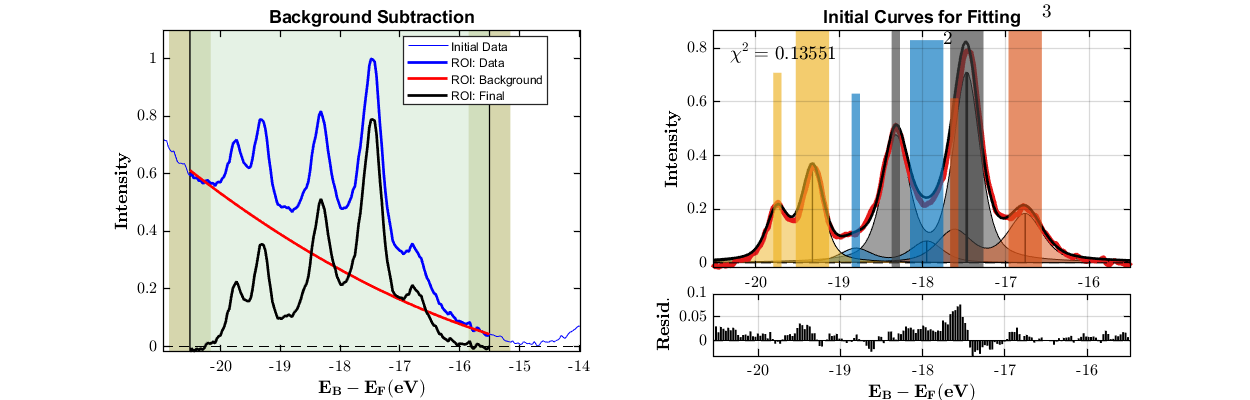

% 2.3 - DEFINING THE BACKGROUND ARGUMENTS
ibgrnd{4} = {[2]};

% 3 - Preview the initial conditions of the model vs data fit
pes2ncurve_view_init(xps_fit.data{1}, cTYPE, iparams, bTYPE, ibgrnd);

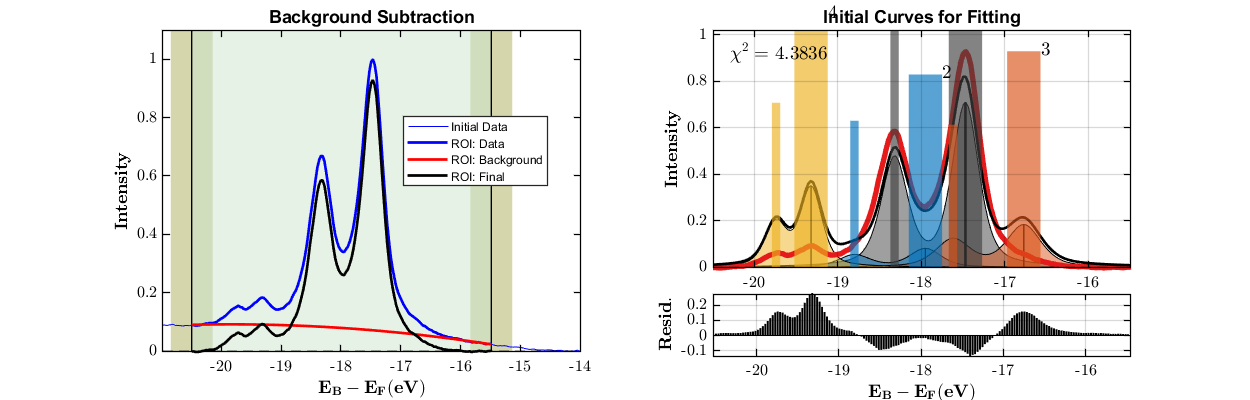

pes2ncurve_view_init(xps_fit.data{end}, cTYPE, iparams, bTYPE, ibgrnd);

**(C) Execute XPS fitting algorithm**

solve_type  = "fmincon";
for i = 1:length(xps_fit.data)
    fprintf("Run %i / %i", i, length(xps_fit.data));
    % -- Solve the fit
    xps_fit.fits{i} = pes2ncurve_solver(xps_fit.data{i}, cTYPE, iparams, bTYPE, ibgrnd, solve_type);
end

Run 1 / 4


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Run 2 / 4


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Run 3 / 4


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Run 4 / 4


Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


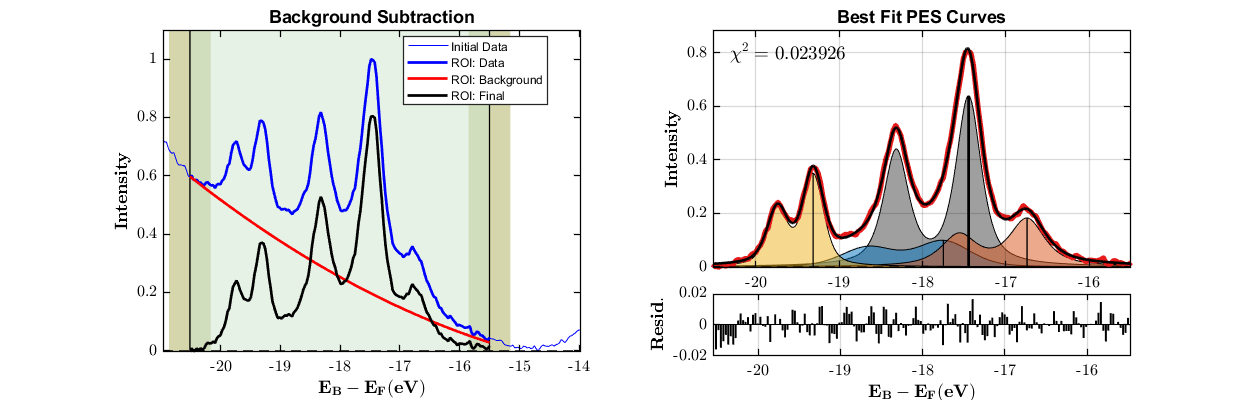

pes2ncurve_view_fit(xps_fit.fits{1});

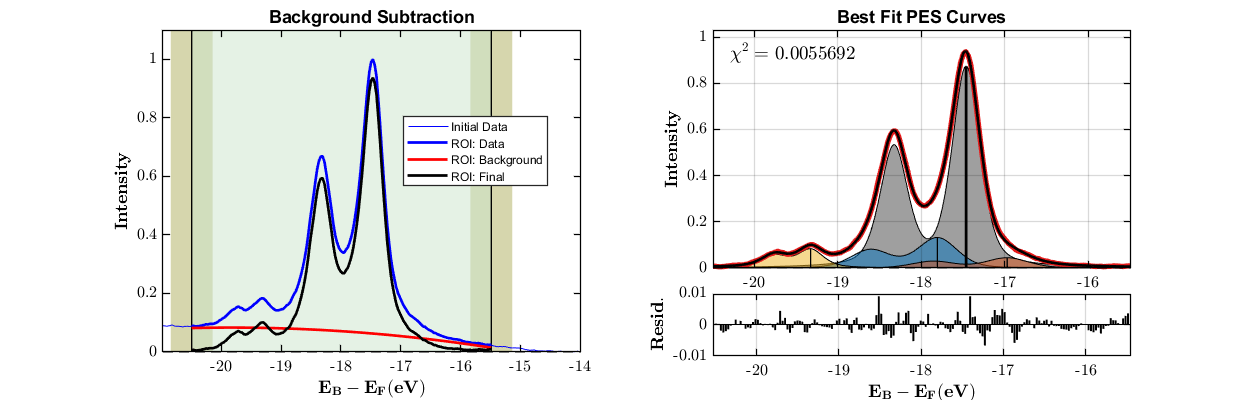

pes2ncurve_view_fit(xps_fit.fits{end});

**(D) Finding the best estimate of ECLs across the dataset**

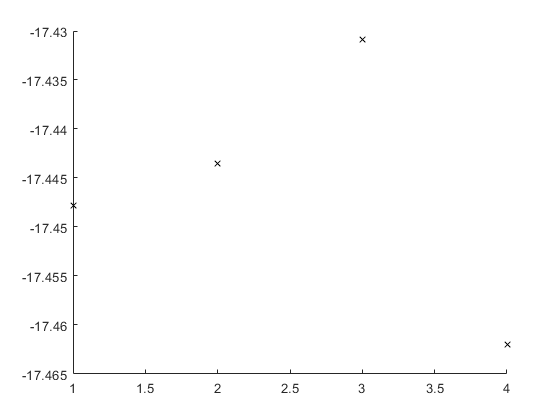

ECL = []; CHISQ = [];
for i = 1:length(xps_fit.fits)
    ECL(i)      = xps_fit.fits{i}.BE(1);
    CHISQ(i)    = xps_fit.fits{i}.CHISQ;
end
% Isolating any potential outliers
XX              = 1:length(ECL);
TF              = isoutlier(ECL); % TF(1:end) = 0;
ECL_adj{1}      = ECL(~TF);
ECL_adj{2}      = ECL(TF);
XX_adj{1}       = XX(~TF);
XX_adj{2}       = XX(TF);
% -- Plotting the result of outlier analysis
figure(); hold on;
plot(XX_adj{1}, ECL_adj{1}, 'kx');

plot(XX_adj{2}, ECL_adj{2}, 'rx');
% -- Redefining ECL and CHISQ
ECL         = ECL(~TF);
CHISQ       = CHISQ(~TF);
% -- Band-offset determination
ECL_mu      = mean(ECL)

ECL_mu = -17.4461

ECL_3sig    = 3*std(ECL)

ECL_3sig = 0.0385

CHISQ_mu    = mean(CHISQ)

CHISQ_mu = 0.0108

CHISQ_3sig  = 3*std(CHISQ)

CHISQ_3sig = 0.0272

**(E) -  Saving the XPS data & fit results**

% Defining the MATLAB data structure
dataStr_02                          = struct();
% - Best Fit XPS Results for Aluminium covered sample
% -- XPS data and corresponding best fits
dataStr_02.repeated_measures       = xps_fit.repeats;
dataStr_02.xps_data                = xps_fit.data;
dataStr_02.xps_fits                = xps_fit.fits;
% -- ECL estimates & measurement uncertainty
dataStr_02.ECL                     = ECL;
dataStr_02.ECL_mu                  = ECL_mu;
dataStr_02.ECL_3sig                = ECL_3sig;
% -- CHISQ estimates
dataStr_02.CHISQ                   = CHISQ;
dataStr_02.CHISQ_mu                = CHISQ_mu;
dataStr_02.CHISQ_3sig              = CHISQ_3sig;
dataStr_02

dataStr_02 = struct with fields:
    repeated_measures: 4
             xps_data: {1×4 cell}
             xps_fits: {1×4 cell}
                  ECL: [-17.4478 -17.4435 -17.4309 -17.4620]
               ECL_mu: -17.4461
             ECL_3sig: 0.0385
                CHISQ: [0.0239 0.0096 0.0041 0.0056]
             CHISQ_mu: 0.0108
           CHISQ_3sig: 0.0272

**(F) -  Saving the corresponding figure & text file with fit results**

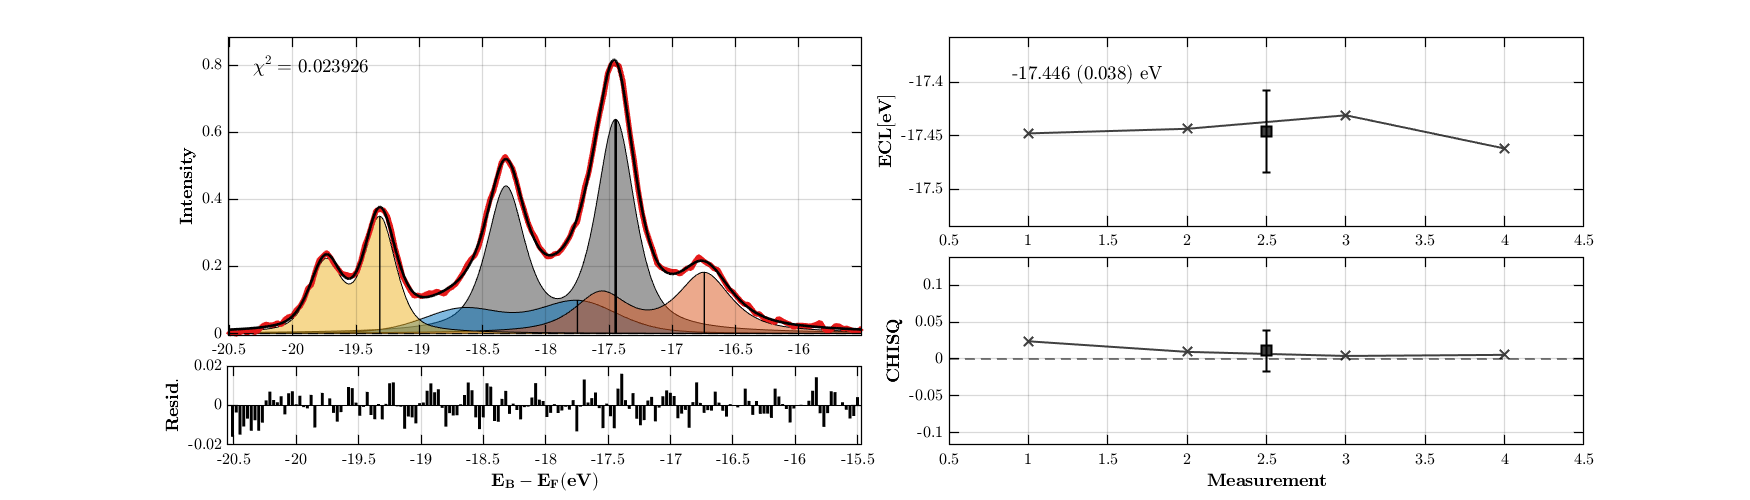

% Initialising the figure
pp  = plot_props();
fig = figure();
fig.Position(3) = 3.5*pp.fig5x4(1);
fig.Position(4) = 1.25*pp.fig5x4(2);
index = 1;

% (1) PLOTTING THE BEST FIT TO THE XPS DATA
subplot(4,4,[1,2,5,6,9,10]); hold on;
% -- Plotting all of the curve components
for i = 1:dataStr_02.xps_fits{index}.nSTATES
    area(dataStr_02.xps_fits{index}.XX, dataStr_02.xps_fits{index}.cYY(:,i), 'FaceColor', pp.col.fit{i}, 'FaceAlpha', pp.falpha, 'EdgeAlpha', 0);
    plot(dataStr_02.xps_fits{index}.XX, dataStr_02.xps_fits{index}.cYY(:,i), 'k-', 'linewidth', 0.25);
end
% -- Plotting the curve component energy locations
for i = 1:dataStr_02.xps_fits{index}.nSTATES
    if i == 1; lWidth = pp.llwidth; else; lWidth = pp.lwidth; end
    line([dataStr_02.xps_fits{index}.cPARAMS(i,1), dataStr_02.xps_fits{index}.cPARAMS(i,1)], [0, max(dataStr_02.xps_fits{index}.cYY(:,i))],...
        'Color', [0 0 0], 'LineWidth', lWidth, 'Linestyle', '-');
end
% -- Plotting the experimental and fit spectra
plot(dataStr_02.xps_fits{index}.X, dataStr_02.xps_fits{index}.DB, 'k-', 'color', pp.col.dat{index}, 'linewidth', 2*pp.llwidth);
plot(dataStr_02.xps_fits{index}.XX, dataStr_02.xps_fits{index}.YY, 'k-', 'Color', pp.col.dat{2}, 'linewidth', 2*pp.lwidth);
% -- Add annotation for the quality of fit
text(0.04, 0.90, "$$ \chi^2 = $$ " + string(dataStr_02.xps_fits{index}.CHISQ),...
    'interpreter', 'latex', 'fontsize', 14, 'color', 'k', 'Units','normalized');
% - Formatting the figure
gca_props(); grid on;
% xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Intensity$$', 'Interpreter', 'latex');
if min(dataStr_02.xps_fits{index}.DB(:)) < dataStr_02.xps_fits{index}.YY; min_y_val = min(dataStr_02.xps_fits{index}.DB(:));
else; min_y_val = min(dataStr_02.xps_fits{index}.YY(:)); 
end
if min_y_val > 0; min_y_val = 0; end
axis([min(dataStr_02.xps_fits{index}.X(:)), max(dataStr_02.xps_fits{index}.X(:)), min_y_val, 1.10*max(dataStr_02.xps_fits{index}.DB(:))]);

% (2) PLOTTING THE CHI-SQUARED OF BEST FIT
subplot(4,4,[13,14]); hold on;
bar(dataStr_02.xps_fits{index}.X, dataStr_02.xps_fits{index}.R, 'facecolor', [0 0 0]);
gca_props(); grid on;
xlabel('$$ \bf  E_B - E_F (eV) $$', 'Interpreter', 'latex');
ylabel('$$ \bf  Resid. $$', 'Interpreter', 'latex');

% (3) PLOTTING ECL VS MEASUREMENT NUMBER
subplot(4,4,[3,4,7,8]); hold on;
% Plotting ECL vs measurement number
XX = 1:length(dataStr_02.ECL);
plot(XX, dataStr_02.ECL, 'kx-', 'color', pp.col.fit{index}, 'markerfacecolor', pp.col.fit{index}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), dataStr_02.ECL_mu, dataStr_02.ECL_3sig, dataStr_02.ECL_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{index}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, dataStr_02.ECL_mu-dataStr_02.ECL_3sig-0.05, dataStr_02.ECL_mu+dataStr_02.ECL_3sig+0.05]);
% xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  ECL [eV]  $$', 'Interpreter', 'latex');
ECL_str = string(round(dataStr_02.ECL_mu,3)) + " (" + string(round(dataStr_02.ECL_3sig,3)) + ") eV";
text(0.1,0.8,ECL_str,'Interpreter',"latex",'Units',"normalized",'FontSize',14);

% (4) PLOTTING CHISQ VS MEASUREMENT NUMBER
subplot(4,4,[11,12,15,16]); hold on;
% Plotting CHISQ vs measurement number
XX = 1:length(dataStr_02.CHISQ);
plot(XX, dataStr_02.CHISQ, 'kx-', 'color', pp.col.fit{index}, 'markerfacecolor', pp.col.fit{index}, 'linewidth', 1.5,'markersize', 10);
errorbar(mean(XX(:)), dataStr_02.CHISQ_mu, dataStr_02.CHISQ_3sig, dataStr_02.CHISQ_3sig, 0, 0, 'ks-',...
    'color', [0 0 0], 'markerfacecolor', pp.col.fit{index}, 'markersize', 10, 'linewidth', 1.5);
% -- Formatting the figure
grid on; gca_props();
axis([0.5, max(XX)+0.5, dataStr_02.CHISQ_mu-dataStr_02.CHISQ_3sig-0.1, dataStr_02.CHISQ_mu+dataStr_02.CHISQ_3sig+0.1]);
xlabel('$$ \bf  Measurement $$', 'Interpreter', 'latex');
ylabel('$$ \bf  CHISQ  $$', 'Interpreter', 'latex');


% (6) SAVING A TEXT FILE
% -- Creating an information string
info = "";
info = info + sprintf("Repeats: \t\t %i \n",              dataStr_02.repeated_measures);
info = info + sprintf("ECL: \t\t\t %.3f (%.3f) eV \n",    dataStr_02.ECL_mu, dataStr_02.ECL_3sig);
info = info + sprintf("CHISQ: \t\t %.3f (%.3f) \n",     dataStr_02.CHISQ_mu, dataStr_02.CHISQ_3sig);
fprintf(info);

Repeats: 		 4 
ECL: 			 -17.446 (0.038) eV 
CHISQ: 		 0.011 (0.027) 
